path = "C:\Users\mnurek\OneDrive - Politechnika Warszawska\PMT-badanie\C1--hv--final00--00000samples.csv";
pmt_data = csvread(path);
pmt_data = pmt_data';
waveform = pmt_data(:,80);
waveform_len = length(waveform);

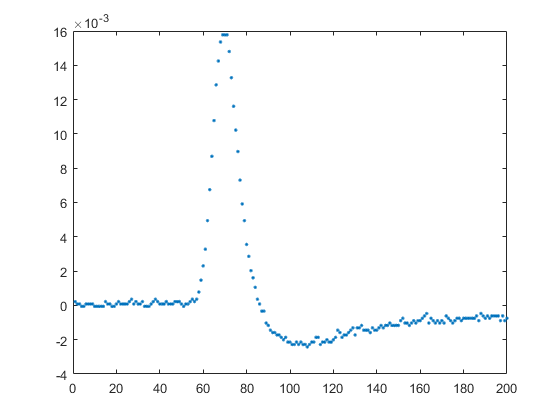

plot(1:waveform_len, waveform, ".")

% FFT interpolation of original waveform
brb_interpolation_factor = 4; %Ts 8ns -> 2ns

interpolation_factor = 25; %Ts 2ns -> 80ps
interpolated_waveform = interpft(waveform,waveform_len * interpolation_factor);
interpolated_waveform_len = length(interpolated_waveform)

interpolated_waveform_len = 5000


final_interpolation_factor = brb_interpolation_factor*interpolation_factor;

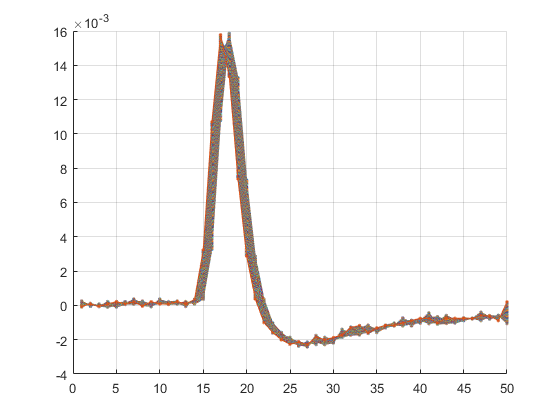

% Get amplitude paramater for different Ts 8ns waveforms
amplitude_parameters = zeros(1, 1 * final_interpolation_factor);
figure; hold on; grid on;
for n = 1 : 1 * final_interpolation_factor
    current_waveform = interpolated_waveform(n:final_interpolation_factor:interpolated_waveform_len);
    amplitude_parameters(n) = get_amplitude_parameter(current_waveform);
    plot(1:length(current_waveform), current_waveform, ".-")
end
hold off;

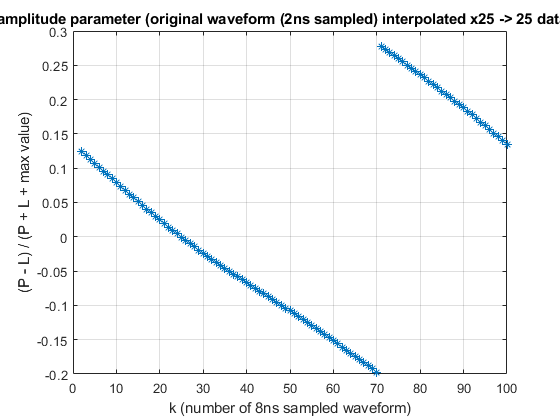

plot(2:length(amplitude_parameters), amplitude_parameters(2:end), "*"); grid on;
title("peak amplitude parameter (original waveform (2ns sampled) interpolated x25 -> 25 data points)")
ylabel("(P - L) / (P + L + max value)")
xlabel("k (number of 8ns sampled waveform)")

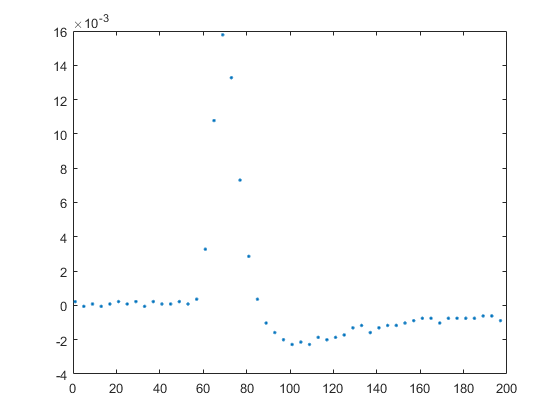

amplitude_parameter = 0.0253

% Function to retrieve the fs = 8 ns waveform from original delayed by k
% original samples
x1 = 1:4:waveform_len;
x2 = 2:4:waveform_len;
x3 = 3:4:waveform_len;
x4 = 4:4:waveform_len;
plot(x1, waveform(x1), ".")

function [amplitude_parameter] = get_amplitude_parameter(waveform)
    % Find maximum index for waveform
    [max_value, max_index] = max(waveform);
    
    L1_index = max_index - 1;
    L2_index = max_index - 2;
    P1_index = max_index + 1;
    P2_index = max_index + 2;
    L = waveform(L1_index) + waveform(L2_index);
    P = waveform(P1_index) + waveform(P2_index);
    sum_in_peak = L + P + max_value;
    amplitude_parameter = (P - L) / sum_in_peak;
end